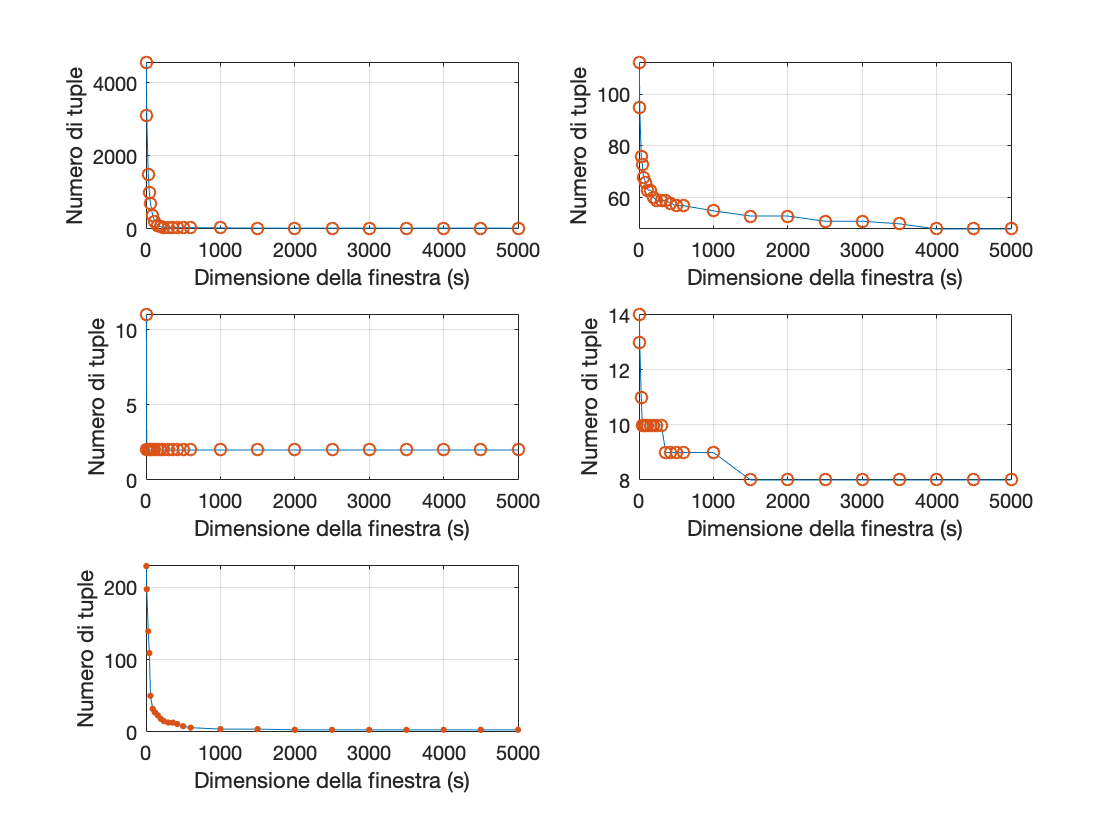

%tg-c401
CWIN = [5 
10 
30 
45 
60
90
120
160
200
240
300
360
420
500
600
1000
1500
2000
2500
3000
3500
4000
4500
5000];
n_tuple_mercury = [4541
3113
1504
1004
 693
 369
 207
 97
 59
 48
 40
 37
 37
 37
 37
 31
 25
 25
 24
 24
 24
 24
 24
 24];
subplot(3,2,1);
plot(CWIN,n_tuple_mercury,CWIN,n_tuple_mercury,'o')
xlabel('Dimensione della finestra (s)')
ylabel('Numero di tuple')
grid on
%tg-master
n_tuple_bgl=[112
95
76
73
68
66
63
63
60
59
59
59
58
57
57
55
53
53
51
51
50
48
48
48];
subplot(3,2,2);
 plot(CWIN,n_tuple_bgl,CWIN,n_tuple_bgl,'o')
xlabel('Dimensione della finestra (s)')
ylabel('Numero di tuple')
grid on
%tg-c572
n_tuple_bgl=[11
2
2
2
2
2
2
2
2
2
2
2
2
2
2
2
2
2
2
2
2
2
2
2];
subplot(3,2,3);
 plot(CWIN,n_tuple_bgl,CWIN,n_tuple_bgl,'o')
xlabel('Dimensione della finestra (s)')
ylabel('Numero di tuple')
grid on
%tg-s044
n_tuple_bgl=[14
13
11
10
10
10
10
10
10
10
10
9
9
9
9
9
8
8
8
8
8
8
8
8];
subplot(3,2,4);
 plot(CWIN,n_tuple_bgl,CWIN,n_tuple_bgl,'o')
xlabel('Dimensione della finestra (s)')
ylabel('Numero di tuple')
grid on
%tg-c238
n_tuple_bgl=[229
197
139
109
50
32
27
23
18
15
13
13
11
8
6
4
4
3
3
3
3
3
3
3];
subplot(3,2,5);
 plot(CWIN,n_tuple_bgl,CWIN,n_tuple_bgl,'o')
xlabel('Dimensione della finestra (s)')
ylabel('Numero di tuple')
grid on
saveas(gcf,'tupleCountMercury-nodes','png');

%R71-M0-N4
CWIN = [5 
10 
30 
45 
60
90
120
160
200
240
300
360
420
500
600
1000
1500
2000
2500
3000
3500
4000
4500
5000];
n_tuple_mercury = [100
100
98
98
96
96
91
78
75
74
72
72
72
72
71
70
70
69
68
67
66
65
64
62];
subplot(3,2,1);
plot(CWIN,n_tuple_mercury,CWIN,n_tuple_mercury,'o')
xlabel('Dimensione della finestra (s)')
ylabel('Numero di tuple')
grid on
%R12-M0-N0
n_tuple_bgl=[112
95
76
73
68
66
63
63
60
59
59
59
58
57
57
55
53
53
51
51
50
48
48
48];
subplot(3,2,2);
 plot(CWIN,n_tuple_bgl,CWIN,n_tuple_bgl,'o')
xlabel('Dimensione della finestra (s)')
ylabel('Numero di tuple')
grid on
%tg-c572
n_tuple_bgl=[11
2
2
2
2
2
2
2
2
2
2
2
2
2
2
2
2
2
2
2
2
2
2
2];
subplot(3,2,3);
 plot(CWIN,n_tuple_bgl,CWIN,n_tuple_bgl,'o')
xlabel('Dimensione della finestra (s)')
ylabel('Numero di tuple')
grid on
%tg-s044
n_tuple_bgl=[14
13
11
10
10
10
10
10
10
10
10
9
9
9
9
9
8
8
8
8
8
8
8
8];
subplot(3,2,4);
 plot(CWIN,n_tuple_bgl,CWIN,n_tuple_bgl,'o')
xlabel('Dimensione della finestra (s)')
ylabel('Numero di tuple')
grid on
%tg-c238
n_tuple_bgl=[229
197
139
109
50
32
27
23
18
15
13
13
11
8
6
4
4
3
3
3
3
3
3
3];
subplot(3,2,5);
 plot(CWIN,n_tuple_bgl,CWIN,n_tuple_bgl,'o')
xlabel('Dimensione della finestra (s)')
ylabel('Numero di tuple')
grid on
saveas(gcf,'tupleCountMercury-nodes','png');

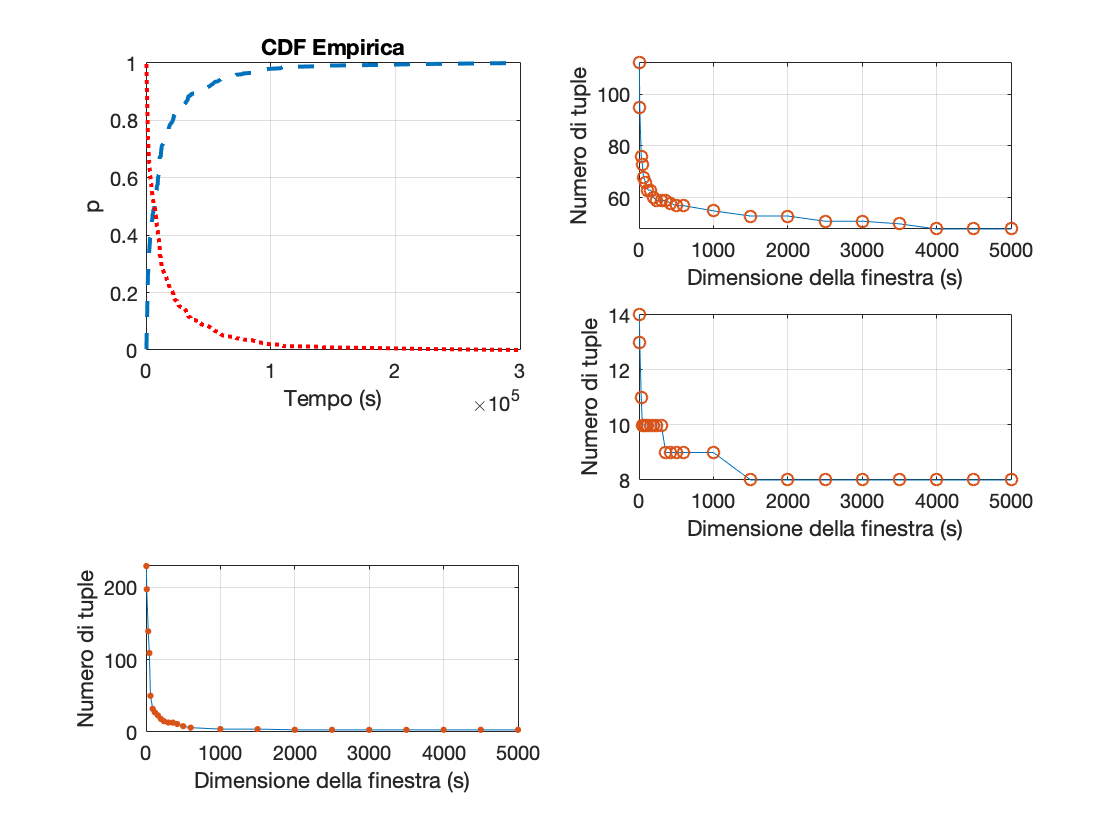

id = fopen("/Users/marcoriccio/Documents/Gruppo15/Homework-IE-18-19/5/design/ffdatoolsetIE2016/tupling_MercuryErrorLog-360/interarrivals.txt");
intarrivals = fscanf(id,'%d');
[p,t]=cdfcalc(intarrivals);
ttf=p(2:size(p,1));
rel = 1-ttf;

subplot(2,2,1)
plot(t,ttf,'--',t,rel,':r','LineWidth',2);
xlabel('Tempo (s)')
ylabel('p')
grid on
title('CDF Empirica');

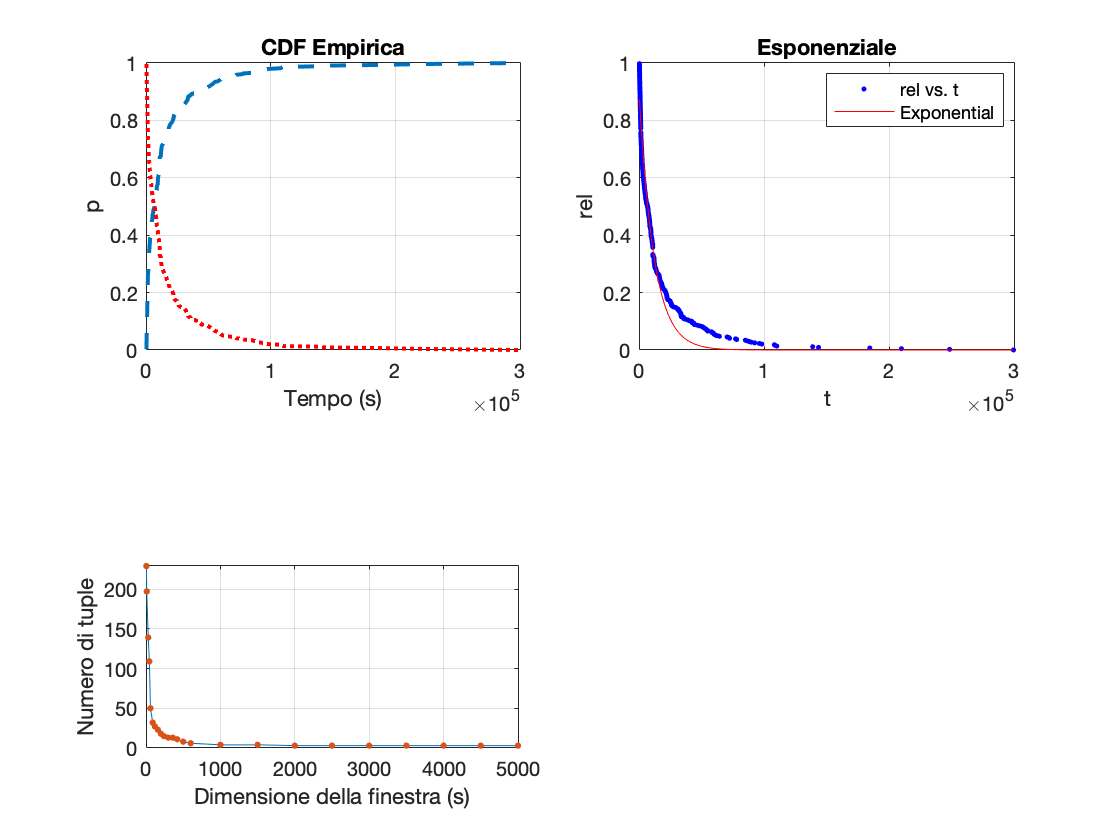


%Esponenziale
[xData, yData] = prepareCurveData( t, rel );
% Set up fittype and options.
ft = fittype( 'exp1' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.352131586294421 -2.22768270295095e-05];
% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

%plot Esponenziale
subplot(2,2,2);
h = plot( fitresult, xData, yData );
legend( h, 'rel vs. t', 'Exponential', 'Location', 'NorthEast' );
% Label axes
xlabel t
ylabel rel
grid on
title('Esponenziale')


%Iper_esponenziale
[xData, yData] = prepareCurveData( t, rel );
% Set up fittype and options.
ft = fittype( 'exp2' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [1.29618063668875 -2.81249338835857e-05 -0.691281124730794 -2.10979088537547e-05];
% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot Iper-esponenziale
subplot(2,2,3)
h = plot( fitresult, xData, yData );
legend( h, 'rel vs. t', 'Iper-Exponential', 'Location', 'NorthEast' );
% Label axes
xlabel t
ylabel rel
grid on
title('Iper-esponenziale')

%Weibull
%Calcolo di 1 / mean(TTF)
n=length(ttf)

n = 415

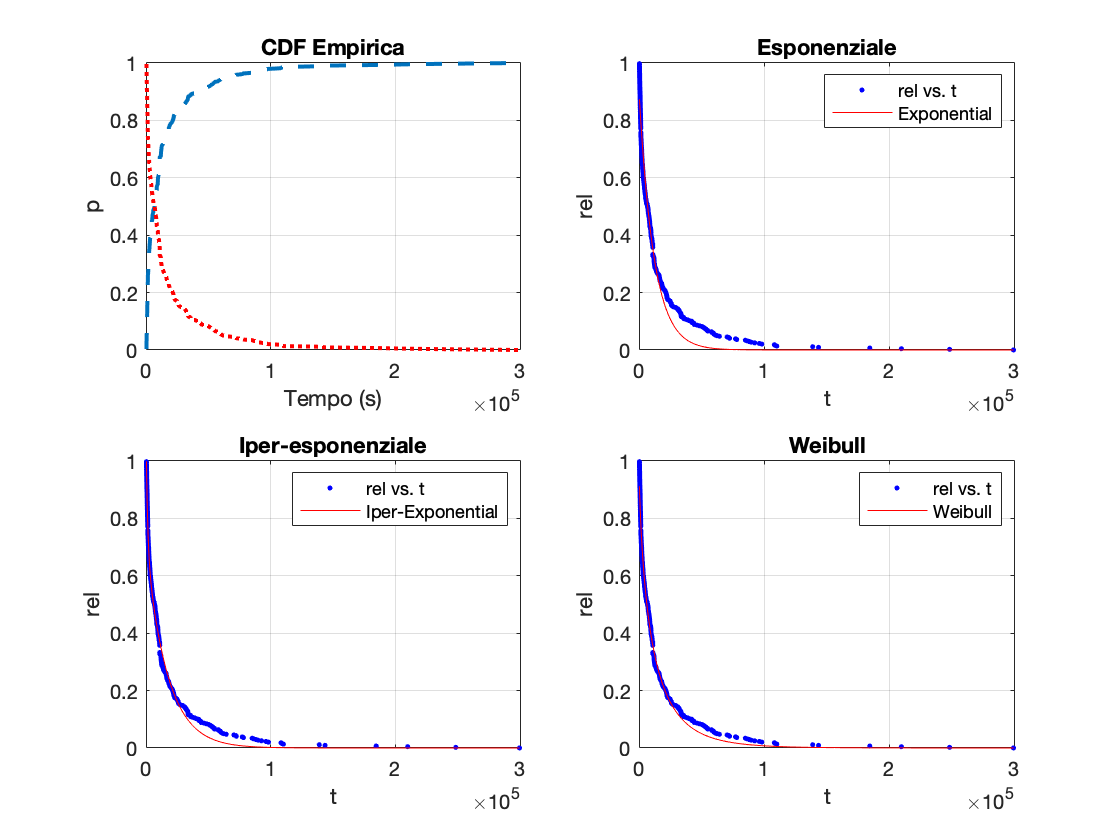

sum=0;
for i=1:n
    sum=sum+ttf(i);
end
ttf_mean=sum/n;
l=1/ttf_mean;

[xData, yData] = prepareCurveData( t, rel );
% Set up fittype and options.
ft = fittype( 'exp(-(l*x)^a)', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.5 0.00001];
% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot Weibull
subplot(2,2,4)
h = plot( fitresult, xData, yData );
legend( h, 'rel vs. t', 'Weibull', 'Location', 'NorthEast' );
% Label axes
xlabel t
ylabel rel
grid on
title('Weibull')
saveas(gcf,'ReliabilityEs1','png')